clear;
close all;
addpath('../include');

isFigure = true; % whether show figure
isSave = true; % whether save related files for evaluation
data_set = 'NEW_COLLEGE'; % 'NEW_COLLEGE' 'KITTI' 'INDOOR'
sequence = '01_short_experiment';
frame_num = 0;
frame_num = frame_num+1;

NEW_COLLEGE_reading_dir = '../example_data/new_college_dataset';
NEW_COLLEGE_saving_dir = '../example_data/NEW_COLLEGE_results';
NEW_COLLEGE_continuous_saving_dir = '../example_data/NEW_COLLEGE_continuous_results';

% lidarConfig
full_num_lasers = 64; % total channel of the input point cloud
num_lasers = 64; % number of channels that will be processed
img_length = 1024; % length of the dedpth image when point cloud transfered into depth image
length_percentage = []; % percentage of points that will be preserved depend on the max distance of the point cloud
max_length = []; % points will be removed larger than this value, which depends on 'length_percentage'
min_length = []; % points will be removed lower than this value
row_times = 2; % row times that upsampling will be done (integer)
col_times = 2; % 1 2 "adjust" "affect sampling result"
fov_up = []; % lidar vertical FoV configuration
fov_down = []; % lidar vertical FoV configuration
lidarConfig = lidar_config_function('data_set',data_set,'num_lasers',num_lasers,'full_num_lasers',full_num_lasers,'img_length',img_length,'row_times',row_times,'col_times',col_times);

% thresholdConfig
avg_filter_thres = 0.5;
rmv_filter_thres = 0.5;
avg_error_thres_patch = 0.5; % Another threshold to break the iteration loop; if 'is_1_1_recons_only=true', this recommand value is 0.01
remove = 0.5; % Remove the points which larger than this error after average error of patch has lower than 'avg_error_thres_patch'
u = []; % the threshold to define a horizontal cliff
v = []; % the threshold to define a vertical cliff
thresholdConfig = threshold_config_function('data_set',data_set,'avg_filter_thres',avg_filter_thres,'rmv_filter_thres',rmv_filter_thres,'avg_error_thres_patch',avg_error_thres_patch,'remove',remove);

% patchConfig
degree_initial = 1;
degree_iter_step = 1;
degree_max = 100;
Pr = 4; % lower Pr with faster extraction speed, more accurate result, high compression percentage.
patch_row_rso = Pr/(lidarConfig.full_num_lasers/lidarConfig.num_lasers)*lidarConfig.row_times; % row patch size
patch_col_rso = Pr*lidarConfig.col_times; % col patch size
row_overlap_step = 2; % row overlap between neighbor patches
col_overlap_step = 2; % col overlap between neighbor patches
k = 9; % adjust the weight between training cell and testing cell
is_1_1_recons_only = false;
if (is_1_1_recons_only) % Relative high precision value with respectly low storage space
    lidarConfig.row_times = 1;
    lidarConfig.col_times = 1;
    thresholdConfig.avg_error_thres_patch = 0.01;    
    patch_row_rso = Pr/(lidarConfig.full_num_lasers/lidarConfig.num_lasers)*lidarConfig.row_times; % row patch size
    patch_col_rso = Pr*lidarConfig.col_times; % col patch size
    row_overlap_step = 0;
    col_overlap_step = 0;
end
patchConfig = patch_config_function('degree_initial',degree_initial,'degree_iter_step',degree_iter_step,'degree_max',degree_max,'patch_row_rso',patch_row_rso,'patch_col_rso',patch_col_rso,'row_overlap_step',row_overlap_step,'col_overlap_step',col_overlap_step,'k',k,'is_1_1_recons_only',is_1_1_recons_only);


% reconsConfig
recons_row_times = 8; % R_row, times that would be increased of row points after reconstruction compared with original point cloud
recons_col_times = 2; % R_col, times that would be increased of coloumn points after reconstruction
reconsConfig = recons_config_function('recons_row_times',recons_row_times,'recons_col_times',recons_col_times,'lidarConfig',lidarConfig);

pose_file = [NEW_COLLEGE_reading_dir '/' sequence '/ground_truth/registered_poses.csv'];
poses = readmatrix(pose_file);
poses(:,2) = poses(:,2).*10^(-6); 
pcd_dir = [NEW_COLLEGE_reading_dir '/' sequence '/ouster_zip_files/ouster_scan'];
pcd_dir_files = dir(pcd_dir);
pcd_dir_files(1:2,:) = [];
% read pcd_file
pcd_file = [pcd_dir '/' pcd_dir_files(frame_num,:).name];

if ~reconsConfig.is_density_enhance
    [inputPointCloud,lidarConfig] = point_cloud_initial_function(data_set,lidarConfig,reconsConfig,pcd_file,pcd_dir_files(frame_num,:).name,frame_num);
    [save_sampling_dir,sampling_remove_dir,save_coefficients_dir,save_recons_dir,save_evaluation_error_dis_file,save_evaluation_compression_file] = create_dir_function(NEW_COLLEGE_continuous_saving_dir,sequence,frame_num,lidarConfig,thresholdConfig,patchConfig,reconsConfig);
else    
    prior_map_file = [NEW_COLLEGE_reading_dir '/03_new_college_prior_map/merged_cloud.ply'];
    prior_map = pcread(prior_map_file); % load the ground truth point cloud map for continuous reconstruction's evaluation (SLOW)
    prior_map = prior_map.Location;
    pose_correction_dir = [NEW_COLLEGE_reading_dir '/transfered_selected_files/results'];
    [inputPointCloud,lidarConfig] = point_cloud_initial_function(data_set,lidarConfig,reconsConfig,pcd_file,pcd_dir_files(frame_num,:).name,frame_num,poses,pose_correction_dir,prior_map);
    [save_sampling_dir,sampling_remove_dir,save_coefficients_dir,save_recons_dir,save_evaluation_error_dis_file,save_evaluation_compression_file] = create_dir_function(NEW_COLLEGE_saving_dir,sequence,frame_num,lidarConfig,thresholdConfig,patchConfig,reconsConfig);
end

C++ Sampling time: 0.384s
Matlab Calculation time 0.061902s
Actual Extraction Time: 0.07(s)


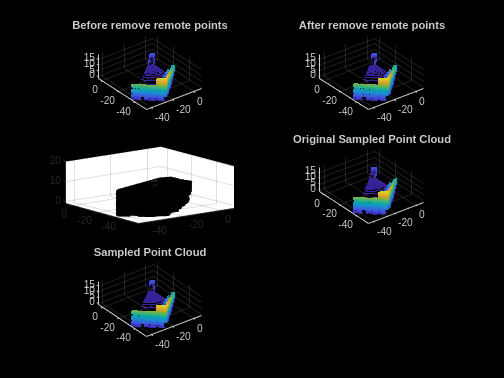

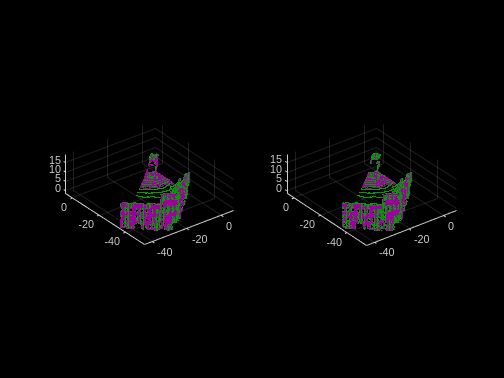

mask grid size shoule be: 56572


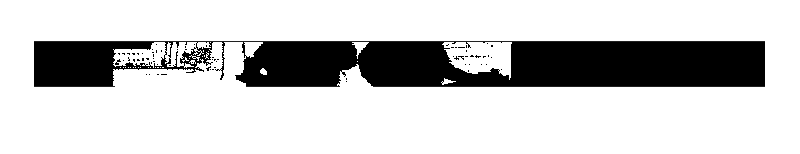

[lidarConfig,coefficient_r_cell,mask_update,point_cloud_original,square_grid,points_up] = SPHARM_extraction_mex(frame_num,inputPointCloud,lidarConfig,thresholdConfig,patchConfig,save_sampling_dir,sampling_remove_dir,save_coefficients_dir,isSave,isFigure);

Reconstruction Time: 0.045(s)


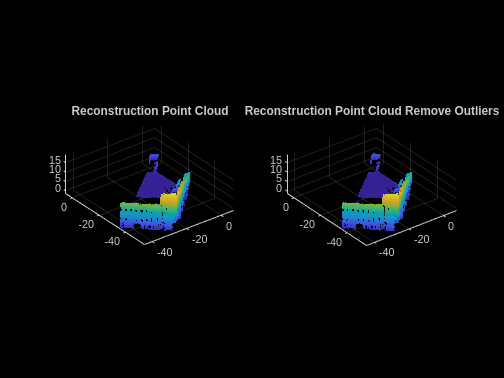

[reconsPointCloud,reconsPointCloudFiltered] = SPHARM_reconstruction_mex(lidarConfig,coefficient_r_cell,mask_update,reconsConfig,save_recons_dir,isSave,isFigure);

% evaluation
if ~reconsConfig.is_density_enhance
    [~,~] = SPHARM_evaluation(data_set,save_coefficients_dir,mask_update,point_cloud_original,reconsPointCloud,frame_num,pcd_dir_files(frame_num,:).name,lidarConfig,reconsConfig,save_evaluation_error_dis_file,save_evaluation_compression_file,isSave,save_sampling_dir);
else
    [~,~] = SPHARM_evaluation(data_set,save_coefficients_dir,mask_update,point_cloud_original,reconsPointCloud,frame_num,pose_correction_dir,pcd_dir_files(frame_num,:).name,poses,prior_map,lidarConfig,reconsConfig,save_evaluation_error_dis_file,save_evaluation_compression_file,isSave,save_sampling_dir);
end

With Density Enhancement
Frame: 0 Mean Distance Error: 0.063229(m) Std: 0.044748
Frame: 0 Mat File Compression Percentage: 23.5369%
Frame: 0 Double Compression Percentage: 20.607%
